# Terahertz band in Body-communication Simulator 

## Description

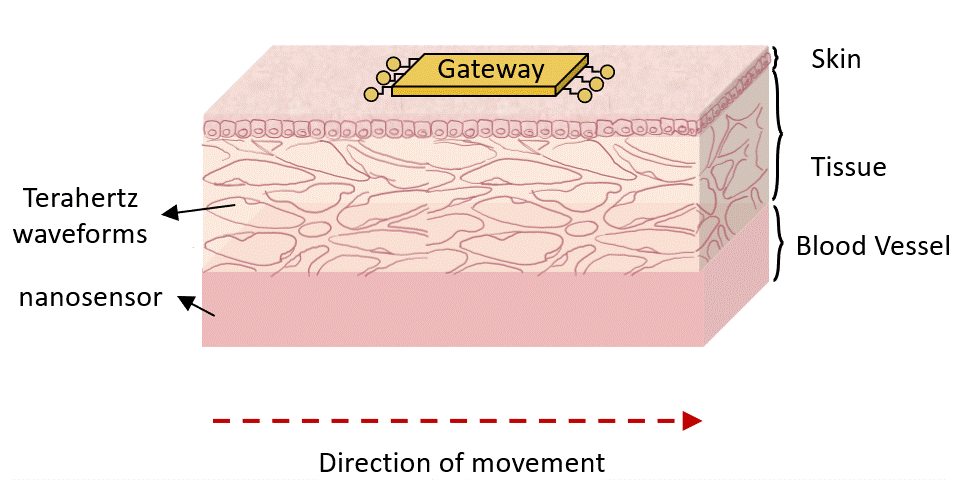

Figure 1: System model.

This code aims to simulate the communication performance between traveling nanosensors in the blood flow and external wearables, as depicted in Fig. 1. The communication is produced in the terahertz band. It takes into account the impact of mobility as the Doppler effect. The modulation format is the binary phase shift keying (BPSK). 

#### Communication Channel Model

The communication channel between the nanosensor and the Gateway is modeled according to the equation [1]:

$r(t)=g_d\,s(t-\tau_d)$, (1)

where $g_d$ is the channel gain, and $\tau_d$ is the propagation delay.

This interface provides adjustable parameters regarding the center frequency for communications, and distance parameters such as the tissue and vessel thickness, as well as the communication range given by the distance between the nanosensor and the Gateway, see Fig. 3. The communication range is always between the minimum and maximum distance lengths.

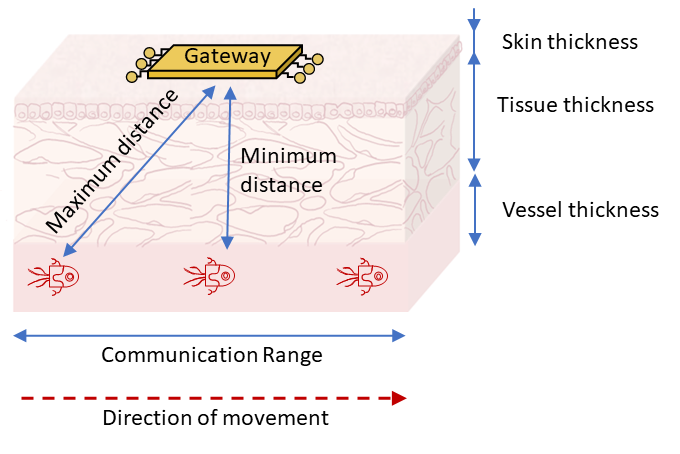

Figure 3: Representation of distances in the tissue.

The communication is modeled in baseband. Constellation points are produced according to the selected waveform (BPSK in this case). The received constellation points are computed after multiplying their amplitude by the channel gain (inverse of the path loss), the transmission delay is considered negligible for the wireless communication in the milli-meter distance.

#### **Mobility model**

The animation in Fig. 4 illustrates the nanosensor's movement along the vessel. The nanosensor moves from left to right following a straight trajectory. The speed of the nanosensor follows the blood speed defined in the Parameters section of this code. 

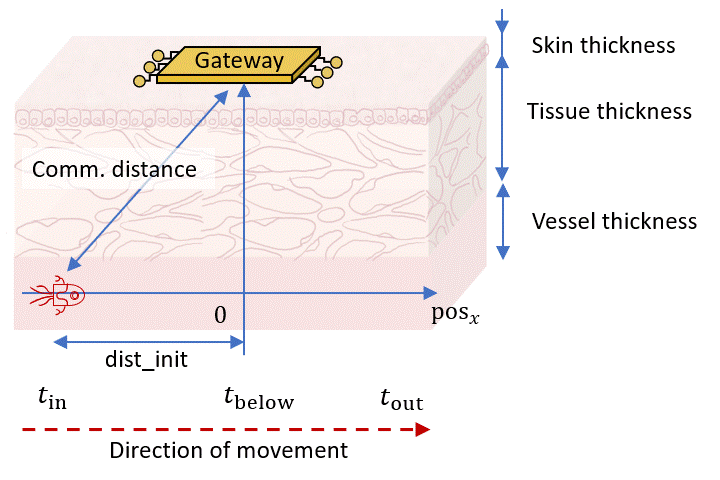

Figure 4: Reference system to evaluate the movement of the nanosensor.

#### Outputs

Outputs are provided regarding the communication scheme as:

- The channel gain versus time: $g_d$ in (1). This is evaluated using the reference in [2].

- The Doppler frequency: $\nu$ according to (2).

- Emmited constellation points.

- Received constellation points

- The achievable bit error rate (BER) versus time.

#### How to run this code

This code runs directly when clicking the run button or updating the parameters below. This code calls to functions implemented in C/C++ (see terahertz.c and terahertz.h). The functions defined in these two files simulate and evaluate the communication system. To re-build these functions, it is needed to install the [MinGW-w64 Compiler (free)](https://www.mathworks.com/help/matlab/matlab_external/install-mingw-support-package.html) and to uncomment lines in the compiling block below.

## Parameters

#### **Physiological  Parameters**

**Tissue and Vessel Thickness in meters, see Fig. 3: **

Skin_thickness =76*10^(-6); %Epidermis, further details in [4]
Tissue_thickness=1000*10^(-6);%Dermis, further details in [5]
Vessel_thickness= 200*10^(-6);%Vessel, further details in [6]

**Blood speed (m/s):**

blood_speed=0.3*10^(-1); %Blood speed according to [7] (aorta: 0.2 m/s, arteries: 0.1 m/s, veins: 0.03 m/s)

#### **Waveform parameters**

**Transmission Power**

P_Tx=5*10^3;

**Carrier frequency**

Freq_Hz=0.5*10^12;

**Bits emission**

bit_rate_bps=1*10^6;%transmission bit rate in the units of Giga bit per second
total_bits=2^(6)*10^3;%total of bits to transmit in Kbits, uncomment lines 29 and 32 below when adjusting this control
bits = randi([0 1],total_bits,1); %emitted bits

**Communication range (meters)**

The initial position is computed based on the dist_init_x value from the control below, see Fig. 4. Based on its value, the initial comm. distance is determined using the Pythagoras theorem.

dist_init_x=850*10^(-6);%distance to the position below the gateway, see Fig. 4 above
Comm_dist_init=sqrt(dist_init_x^2+(Skin_thickness+Tissue_thickness+Vessel_thickness)^2);

**Receiver**

gamma_0_dB=15;%signal to noise ratio threshold

**Waveform**

mod_order="BPSK";
Tx_power_Watts=4*10^3;%typical values are given in [3]
waveform_amplitude=sqrt(Tx_power_Watts);

**Sampling:**

sampling_time=1/bit_rate_bps*10^(-9);

#### **Electric coefficients of human body parts**

%parameters taken from reference [9] except when stated

ALPHA_1_DERMIS = 0.92;
ALPHA_1_EPIDERMIS = 0.95;

ALPHA_2_DERMIS = 0.97;
BETA_1_DERMIS = 0.8;
BETA_1_EPIDERMIS = 0.96;

BETA_2_DERMIS = 0.99;

%Permeability
mu_r=1; %[10]

%Permittivity
EPSILON_0 = 8.85E-12;%free space permittivity

EPSILON_INF_BLOOD = 2.1; %[8]
EPSILON_INF_DERMIS = 4.0;
EPSILON_INF_EPIDERMIS = 3.0;

EPSILON_1_BLOOD = 130.0; %[8]
EPSILON_1_DERMIS = 5.96;
EPSILON_1_EPIDERMIS = 89.61;

EPSILON_2_BLOOD = 3.8; %[8]
EPSILON_2_DERMIS = 380.4;

%Relaxation time
TAU_1_BLOOD = 14.4E-12; %[8]
TAU_1_DERMIS = 1.6E-12;
TAU_1_EPIDERMIS = 15.9E-12;

TAU_2_BLOOD = 0.1E-12; %[8]
TAU_2_DERMIS = 159.0E-9;

%conductivity
SIGMA_DERMIS = 0.1;
SIGMA_EPIDERMIS = 0.01;
SIGMA_BLOOD = 5.37; %mean value in [11]

c_0 = 299792458.0; %speed of light in vacuum

%complex permittivity and refractive index in the blood, Eq. (8) in [2]
epsilon_r_v=EPSILON_INF_BLOOD+(EPSILON_1_BLOOD-EPSILON_2_BLOOD)/(1.0+1i*(2*pi*Freq_Hz)*TAU_1_BLOOD)+(EPSILON_2_BLOOD-EPSILON_INF_BLOOD)/(1.0+1i*(2*pi*Freq_Hz)*TAU_2_BLOOD);
n_v = sqrt(epsilon_r_v);
n_1_v = real(n_v);
n_2_v = -imag(n_v);

%Propagation constant in the blood [12; Eq. (3.17-c)]
gamma_v=sqrt(1i*2*pi*Freq_Hz*mu_r*SIGMA_BLOOD-(2*pi*Freq_Hz)^2*mu_r*epsilon_r_v);

%Phase constant in the blood [12; Eq. (3.17-f)]
beta_v=imag(gamma_v);

%computing the effective Wavelength in the blood
lambda_g_v = c_0/Freq_Hz/n_1_v;
%computing the molecular Absorption Coefficient
mu_abs_v = (4*pi*n_2_v)/lambda_g_v;

%complex permittivity and refractive index Tissue, Eq. (9) in [2]
sum_1 = EPSILON_1_DERMIS/(1.0+(1i*(2*pi*Freq_Hz)*TAU_1_DERMIS)^ALPHA_1_DERMIS)^BETA_1_DERMIS;
sum_2 = EPSILON_2_DERMIS/(1.0+(1i*(2*pi*Freq_Hz)*TAU_2_DERMIS)^ALPHA_2_DERMIS)^BETA_2_DERMIS;
epsilon_r_t = EPSILON_INF_DERMIS+sum_1+sum_2-1i*SIGMA_DERMIS/((2*pi*Freq_Hz)*EPSILON_0);
n_t=sqrt(epsilon_r_t);
n_1_t = real(n_t);
n_2_t = -imag(n_t);

%Propagation constant in the Tissue [12; Eq. (3.17-c)]
gamma_t=sqrt(1i*2*pi*Freq_Hz*mu_r*SIGMA_DERMIS-(2*pi*Freq_Hz)^2*mu_r*epsilon_r_t);

%Phase constant in the Tissue [12; Eq. (3.17-f)]
beta_t=imag(gamma_t);

%computing the effective Wavelength in the Tissue
lambda_g_t = c_0/Freq_Hz/n_1_t;
%computing the molecular Absorption Coefficient
mu_abs_t = (4*pi*n_2_t)/lambda_g_t;

%complex permittivity and refractive index Skin, Eq. (9) in [2]
sum_1 = EPSILON_1_EPIDERMIS/(1.0 + (1i*(2*pi*Freq_Hz)*TAU_1_EPIDERMIS)^ALPHA_1_EPIDERMIS)^BETA_1_EPIDERMIS;
sum_2 = 1i*SIGMA_EPIDERMIS/((2*pi*Freq_Hz)*EPSILON_0);
epsilon_r_s = EPSILON_INF_EPIDERMIS + sum_1 - sum_2;
n_s = sqrt(epsilon_r_s);
n_1_s = real(n_s);
n_2_s = -imag(n_s);

%Propagation constant in the Skin [12; Eq. (3.17-c)]
gamma_s=sqrt(1i*2*pi*Freq_Hz*mu_r*SIGMA_EPIDERMIS-(2*pi*Freq_Hz)^2*mu_r*epsilon_r_s);

%Phase constant in the Skin [12; Eq. (3.17-f)]
beta_s=imag(gamma_s);

beta_v/beta_t

ans = 0.9240

beta_t/beta_s

ans = 1.1530


%computing the effective Wavelength in the Skin
lambda_g_s = c_0/Freq_Hz/n_1_s;
%computing the molecular Absorption Coefficient
mu_abs_s = (4*pi*n_2_s)/lambda_g_s;

#### **Illustrating the channel path-loss**

%illustrating the pathloss and SNR when traveling along the vessel center 
comm_dist_Vessel=Vessel_thickness/2;
comm_dist_Tissue=Tissue_thickness;
comm_dist_Skin=Skin_thickness;

%computing the vessel path-loss
L_v=exp(mu_abs_v*comm_dist_Vessel)*((4*pi*comm_dist_Vessel)/lambda_g_v)^2;
%computing the tissue path-loss
L_t=exp(mu_abs_t*comm_dist_Tissue)*((4*pi*comm_dist_Tissue)/lambda_g_t)^2;
%computing the skin path-loss
L_s=exp(mu_abs_s*comm_dist_Skin)*((4*pi*comm_dist_Skin)/lambda_g_s)^2;
 
pathLoss_dist_dB=10*log10(L_v*L_t*L_s)%traveling through the bottom edge in the vessel

pathLoss_dist_dB = 145.9304


%computing level of noise
kB = 1.38064852e-23; %Boltzman constant
T_0 = 310; %reference temperature
BW = 2*bit_rate_bps; %minimum bandwidth for the given bit rate
N = 4*kB*T_0*BW;
SNR_0_dB=10*log10(P_Tx)-10* log10(N)-pathLoss_dist_dB

SNR_0_dB = 25.7140

## **Communication Performance**

#### **Nanosensor Mobility**

%evaluating the time dimension
% t_in=0;
% t_out=2*dist_init_x/blood_speed;
% time_vector=linspace(t_in,t_out,1000);
time_vector=0:1/bit_rate_bps:1/bit_rate_bps*(total_bits-1);

%evaluating the spatial dimension
%initial position
pos_o=-sqrt(Comm_dist_init^2-(Skin_thickness+Tissue_thickness+Vessel_thickness)^2);
%position with time
pos_x_nanosensor=pos_o+blood_speed*time_vector;
%communication distance with time
comm_dist_time=sqrt(pos_x_nanosensor.^2+(Skin_thickness+Tissue_thickness+Vessel_thickness)^2);

#### **Reception Noise**

%computing level of noise
kB = 1.38064852e-23; %Boltzman constant
T_0 = 310; %reference temperature
BW = 2*bit_rate_bps; %minimum bandwidth for the given bit rate
N = 4*kB*T_0*BW; 

#### Coherence time

%maximum Doppler shift
f_m=blood_speed*Freq_Hz/c_0;
%coherence time
T_c=sqrt(9/16/pi)/f_m;
%total of blocks
M=ceil(total_bits/T_c/(bit_rate_bps*log10(1+10^(gamma_0_dB/10))));
%total of kylo bytes per block
kB_per_block=total_bits/M/2^3/10^3;

#### Outage probability per block

% syms l_v_symb
% %just below the gateway
% figure;
% fplot(exp(mu_abs_v*l_v_symb)*((4*pi*l_v_symb)/lambda_g_v)^2*L_t*L_s-P_Tx/(N*10^(gamma_0_dB/10)),[0 Vessel_thickness],'LineWidth',2); grid on;
% l_v_symb=vpasolve(exp(mu_abs_v*l_v_symb)*((4*pi*l_v_symb)/lambda_g_v)^2-P_Tx/(N*10^(gamma_0_dB/10)*L_t*L_s),l_v_symb,[0 Vessel_thickness]);
% l_v = double(l_v_symb)
% pout_1=1-l_v_symb/Vessel_thickness


bit_rate_bps=(0.5:0.2:10)*10^6;%bit rate vector
%to save the BER vs bit rate
ber_vector=zeros(1,length(bit_rate_bps));

for br=1:length(bit_rate_bps)
    %computing level of noise
    kB = 1.38064852e-23; %Boltzman constant
    T_0 = 310; %reference temperature
    BW = 2*bit_rate_bps(br); %minimum bandwidth for the given bit rate
    N = 4*kB*T_0*BW;
    %store the numerical solutions
    %total of blocks
    M=ceil(total_bits/T_c/(bit_rate_bps(br)*log10(1+10^(gamma_0_dB/10))));
    l_v=zeros(1,M);
    p_out_m=zeros(1,M);    
    %evaluating the outage probability per block
    for m=1:M
        syms l_v_symb 
        %speed along the vessel
        v_lv=4*blood_speed/Vessel_thickness^2*(Vessel_thickness*l_v_symb-l_v_symb^2);
        %coordinates with time
        cos_angle=sqrt(1-(v_lv*(m-1)*T_c/(l_v_symb+Tissue_thickness+Skin_thickness))^2);
        d_v=l_v_symb/cos_angle;
        d_t=Tissue_thickness/cos_angle;
        d_s=Skin_thickness/cos_angle;

        %paht-loss along the human segments
        L_v=exp(mu_abs_v*d_v)*((4*pi*d_v)/lambda_g_v)^2;
        L_t=exp(mu_abs_t*d_t)*((4*pi*d_t)/lambda_g_t)^2;
        L_s=exp(mu_abs_s*d_s)*((4*pi*d_s)/lambda_g_s)^2;

        %solution to the distance in the vessel
%         fplot(L_v*L_t*L_s-P_Tx/(N*10^(gamma_0_dB/10)),[0 Vessel_thickness],'LineWidth',2);grid on; hold on;
%         axis([0 Vessel_thickness -1 1]);
        l_v_symb=vpasolve(L_v*L_t*L_s-P_Tx/(N*10^(gamma_0_dB/10)),l_v_symb,[0 Vessel_thickness]);
        l_v(m) = double(l_v_symb);
        %outage probability
        p_out_m(m)=1-l_v(m)/Vessel_thickness;
    end

#### Plotting Outage probability vs transmission block

%     fontsize=15;
%     
%     stem(0:M-1,p_out_m,'LineWidth',2); grid on; hold on;
%     set(gca, 'XTick', 0:M-1);
%     x_ticks=cell(1,M);
%     x_ticks{1}='$0$';
%     x_ticks{2}='$T_c$';
%     for m=3:M
%         x_ticks{m}=strcat("$",num2str(m-1),"T_c$");
%     end
% 
%     set(gca, 'XTickLabel', x_ticks, 'TickLabelInterpreter', 'latex');
%     xlabel('time','Interpreter','latex');
%     ylabel('Outage probability','Interpreter','latex');
%     set(gca,'FontSize',fontsize);


#### BER

    ber=1;
    for m=1:M
        ber=ber*(1-p_out_m(m)/(total_bits/M));
    end

    ber=1-ber;

    ber_vector(br)=ber;

end

#### Plotting the BER vs BW

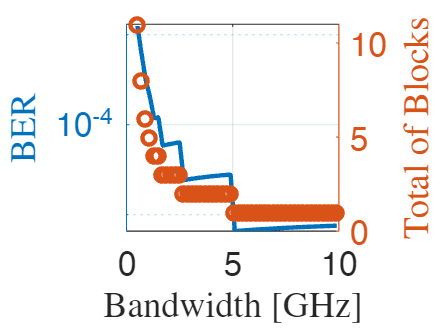

fontsize=15;

figure;
yyaxis left
semilogy(bit_rate_bps/10^6,ber_vector,'LineWidth',2); grid on;
ylabel('BER','Interpreter','latex');
yyaxis right
M=ceil(total_bits/T_c./(bit_rate_bps*log10(1+10^(gamma_0_dB/10))));
plot(bit_rate_bps/10^6,M,'o','LineWidth',2);
ylabel('Total of Blocks','Interpreter','latex');
xlabel('Bandwidth [GHz]','Interpreter','latex');

set(gca,'FontSize',fontsize);

## **References**

[1] G. Matz and F. Hlawatsch, “Fundamentals of Time-Varying Communication Channels,” in Wireless Communications Over Rapidly Time-Varying Channels, F. Hlawatsch and G. Matz, Eds., Elsevier, 2011, pp. 1–63.

[2] J. Simonjan, B. D. Unluturk and I. F. Akyildiz, "In-Body Bionanosensor Localization for Anomaly Detection via Inertial Positioning and THz Backscattering Communication," in IEEE Transactions on NanoBioscience, vol. 21, no. 2, pp. 216-225, April 2022, doi: 10.1109/TNB.2021.3123972.

[3] J. M. Jornet and I. F. Akyildiz, "Channel Modeling and Capacity Analysis for Electromagnetic Wireless Nanonetworks in the Terahertz Band," in IEEE Transactions on Wireless Communications, vol. 10, no. 10, pp. 3211-3221, October 2011, doi: 10.1109/TWC.2011.081011.100545.

[4] G. Piro, P. Bia, G. Boggia, D. Caratelli, L.A. Grieco, L. Mescia, "Terahertz electromagnetic field propagation in human tissues: A study on communication capabilities," Nano Communication Networks, Volume 10, 2016, Pages 51-59, ISSN 1878-7789, [https://doi.org/10.1016/j.nancom.2016.07.010.](https://doi.org/10.1016/j.nancom.2016.07.010.)

[5] P. Oltulu, B. Ince, N. Kokbudak, F. Kılıc¸ ¨ et al., “Measurement of epidermis, dermis, and total skin thicknesses from six different body regions with a new ethical histometric technique,” Turk Plastik, Rekonstr ¨ uktif ve ¨ Estetik Cerrahi Dergisi (Turk J Plast Surg), vol. 26, no. 2, pp. 56–61, 2018. DOI: 10.4103/tjps.TJPS_2_17

[6] M. Fruchard, L. Arcese, and E. Courtial, “Estimation of the blood velocity for nanorobotics,” IEEE Transactions on Robotics, vol. 30, no. 1, pp. 93–102, 2013.

[7] A. C. Guyton and M. E. Hall, Guyton and Hall Textbook of Medical Physiology, 14th ed. Elsevier, 2015.

[8] C. B. Reid, G. Reese, A. P. Gibson, and V. P. Wallace, “Terahertz time-domain spectroscopy of human blood,” *IEEE J. Biomed. health Informat. *, vol. 17, no. 4, pp. 774–778, Jul. 2013 .

[9]  G. Piro, P. Bia, G. Boggia, D. Caratelli, L. A. Grieco, and L. Mescia, “Terahertz electromagnetic field propagation in human tissues: A study on communication capabilities,” *Nano Commun. Netw.*, vol. 10, pp. 51–59, Dec. 2016.

[10] H. Elayan, R. M. Shubair, J. M. Jornet, and P. Johari, “Terahertz Channel Model and Link Budget Analysis for Intrabody Nanoscale Communication,” IEEE Transactions on NanoBioscience, vol. 16, no. 4, pp. 491–503, Jun. 2017.

[11] N. Ištuk *et al*., "Measurement of Electrical Conductivity of Human Blood at Frequencies Below 100 kHz with Four-electrode Probe Method," *2021 XXXIVth General Assembly and Scientific Symposium of the International Union of Radio Science (URSI GASS)*, 2021, pp. 1-4, doi: 10.23919/URSIGASS51995.2021.9560424.

[12] C. Balanis, Advanced Engineering Electromagnetics, 2nd ed. Wiley, 2012, p. 1040.